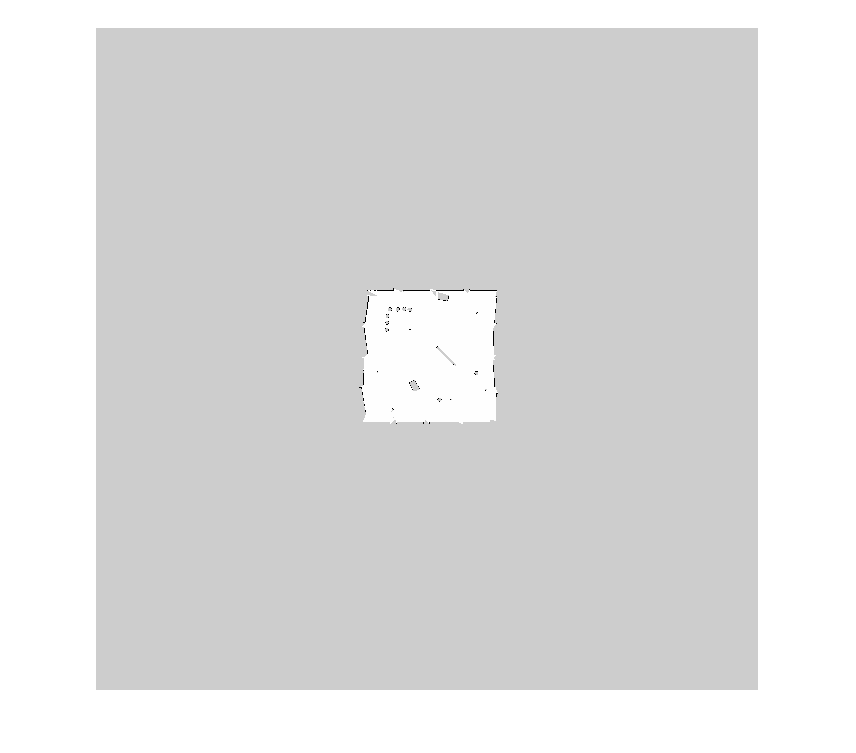

% Load the occupancy map of the environment
image = imread('/home/df/Downloads/playpen_map.pgm');
imageCropped = image();
imshow(imageCropped);

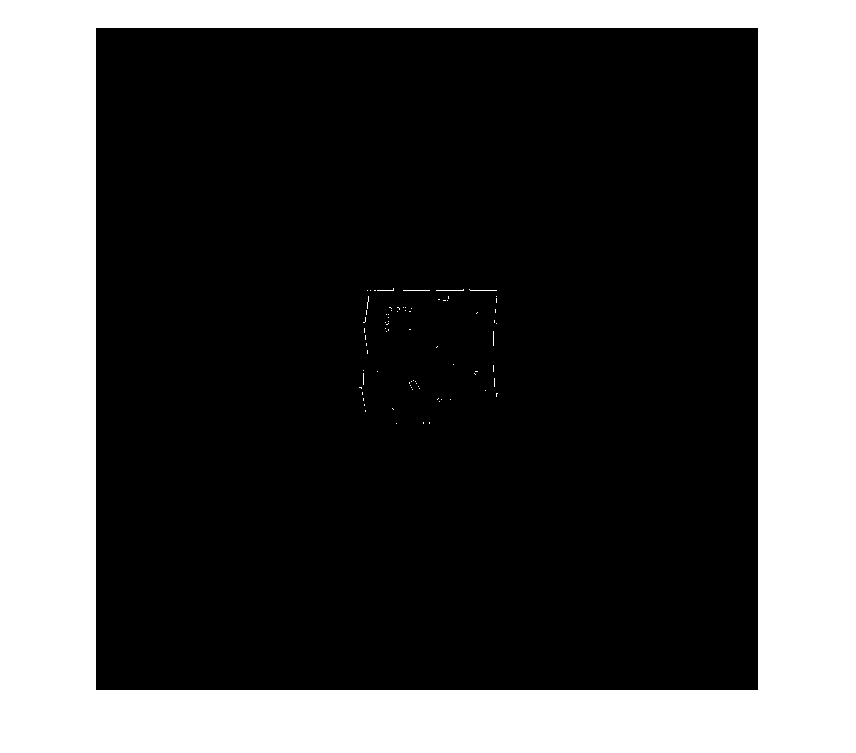

%% 

imageBW = image < 100;
imshow(imageBW);

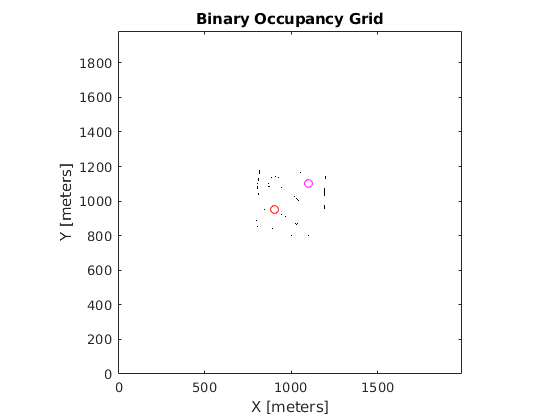


figure;
tb3map = binaryOccupancyMap(imageBW);
show(tb3map)
%% 


% Define start and goal points on the map
start = [900.0,950.0, -pi];
goal = [1100.0, 1100.0, 0];

% Set the start and goal positions of the robot
hold on
plot(start(1), start(2), 'ro')
plot(goal(1), goal(2), 'mo')

hold off

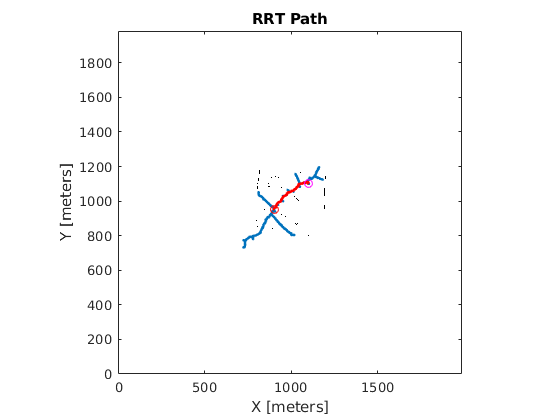


bounds = [tb3map.XWorldLimits; tb3map.YWorldLimits; [-pi pi]];

% Specify the state space of the robot and the min turning radius
ss = stateSpaceDubins(bounds);
ss.MinTurningRadius = 2;

% Vaidate states and discretize motion
stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = tb3map;
stateValidator.ValidationDistance = 0.05;

% Create a path planner and set parameters
planner = plannerRRT(ss, stateValidator);
planner.MaxConnectionDistance = 2.0;
planner.MaxIterations = 20000;


%planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

% Plan a path
[pthObj, solnInfo] = plan(planner, start, goal);

wayPoints = (pthObj.States(:,[1,2]));

%to convert into world files
wayPoints = (wayPoints*0.05);
wayPoints = wayPoints - 50;
%len = length(wayPoints);
%wayPoints(len+1) = wayPoints(len);

%wayPoints2 = [wayPoints; length(wayPoints)];
wayPoints(end+1,:) = NaN;


% Display the map
show(tb3map)
hold on

% Search tree
plot(solnInfo.TreeData(:,1), solnInfo.TreeData(:,2), '.-');
%% 

% Interpolate and plot path
interpolate(pthObj, pthObj.NumStates)
plot(pthObj.States(:,1), pthObj.States(:,2), 'r-', 'LineWidth', 2)

% Show the start and goal in the grid map
plot(start(1), start(2), 'ro')
plot(goal(1), goal(2), 'mo')
title('RRT Path')
hold off



% function isReached = exampleHelperCheckIfGoal(planner, goalState, newState)
%     isReached = false;
%     threshold = 0.1;
%     if planner.StateSpace.distance(newState, goalState) < threshold
%         isReached = true;
%     end
% end